%rng('default')
dataFolder = 'data/Separate_STFT_addNoise_Class';
% dataFolder = 'data/One_STFT'; % for training one STFT frame per audio

imds = imageDatastore(dataFolder, ...
    'IncludeSubfolders',true, ...
    'LabelSource', 'foldernames');

trainingNumFiles = 0.7;
[imdsTrain, imdsValidation] = splitEachLabel(imds, trainingNumFiles, 'randomize');

net = vgg19;

%net.Layers('input');
inputSize = net.Layers(1).InputSize;

## Replace final layers

if isa(net,'SeriesNetwork') 
  lgraph = layerGraph(net.Layers); 
else
  lgraph = layerGraph(net);
end

## Find the names of the two layers to replace

[learnableLayer,classLayer] = findLayersToReplace(lgraph);


numClasses = numel(categories(imdsTrain.Labels));

if isa(learnableLayer,'nnet.cnn.layer.FullyConnectedLayer')
    newLearnableLayer = fullyConnectedLayer(numClasses, ...
        'Name','new_fc', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
    
elseif isa(learnableLayer,'nnet.cnn.layer.Convolution2DLayer')
    newLearnableLayer = convolution2dLayer(1,numClasses, ...
        'Name','new_conv', ...
        'WeightLearnRateFactor',10, ...
        'BiasLearnRateFactor',10);
end

lgraph = replaceLayer(lgraph,learnableLayer.Name,newLearnableLayer);

newClassLayer = classificationLayer('Name','new_classoutput');
lgraph = replaceLayer(lgraph,classLayer.Name,newClassLayer);

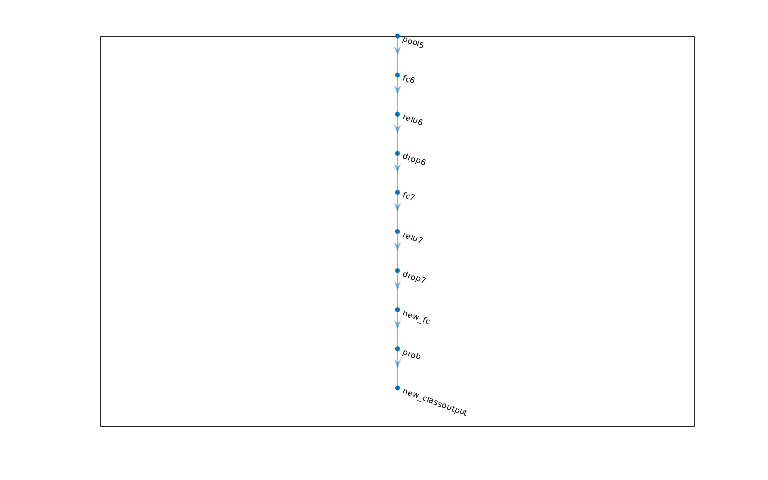

figure('Units','normalized','Position',[0.3 0.3 0.4 0.4]);
plot(lgraph)
ylim([0,10])

## Freeze Initial Layers

layers = lgraph.Layers;
connections = lgraph.Connections;

layers(1:10) = freezeWeights(layers(1:10));
lgraph = createLgraphUsingConnections(layers,connections);

## Train Network

pixelRange = [-30 30];
scaleRange = [0.9 1.1];
imageAugmenter = imageDataAugmenter( ...
    'RandXReflection',true);
augimdsTrain = augmentedImageDatastore(inputSize(1:2),imdsTrain, ...
    'DataAugmentation',imageAugmenter);

## To automatically resize the validation images without performing further data augmentation, use an augmented image datastore without specifying any additional preprocessing operations.

augimdsValidation = augmentedImageDatastore(inputSize(1:2),imdsValidation);

miniBatchSize = 10;
valFrequency = floor(numel(augimdsTrain.Files)/miniBatchSize);
options = trainingOptions('sgdm', ...
    'MiniBatchSize',miniBatchSize, ...
    'MaxEpochs',50, ...
    'InitialLearnRate',3e-4, ...
    'Shuffle','every-epoch', ...
    'ValidationData',augimdsValidation, ...
    'ValidationFrequency',valFrequency, ...
    'Verbose',false, ...
    'Plots','training-progress');

net = trainNetwork(augimdsTrain,lgraph,options);

save net;
%load('net.mat');


## Confusion matrix

[YPred,probs] = classify(net,augimdsValidation);
accuracy = mean(YPred == imdsValidation.Labels)

accuracy = 0.9877

## Confusion matrix

Create a confusion matrix chart from the true lprobsabels Y and the predicted labels predictedY.

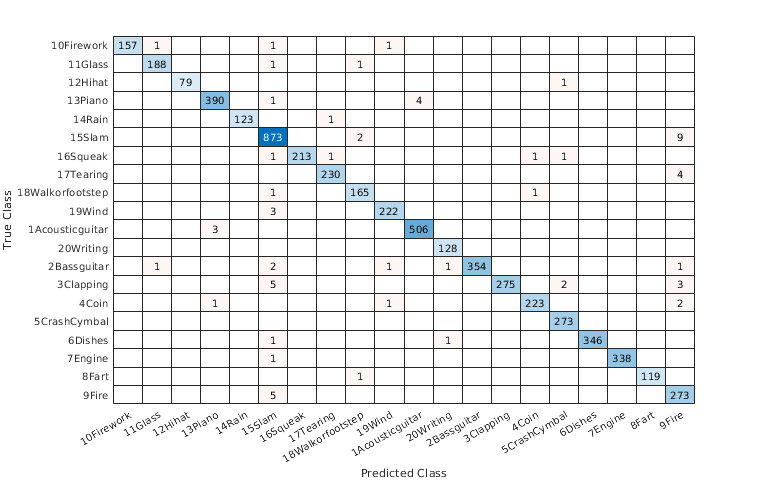

Y = imdsValidation.Labels;
cm = confusionchart(Y,YPred);

cm.NormalizedValues

Unable to resolve the name cm.NormalizedValues.

## Modify the appearance and behavior of the confusion matrix chart by changing property values. Add a title.

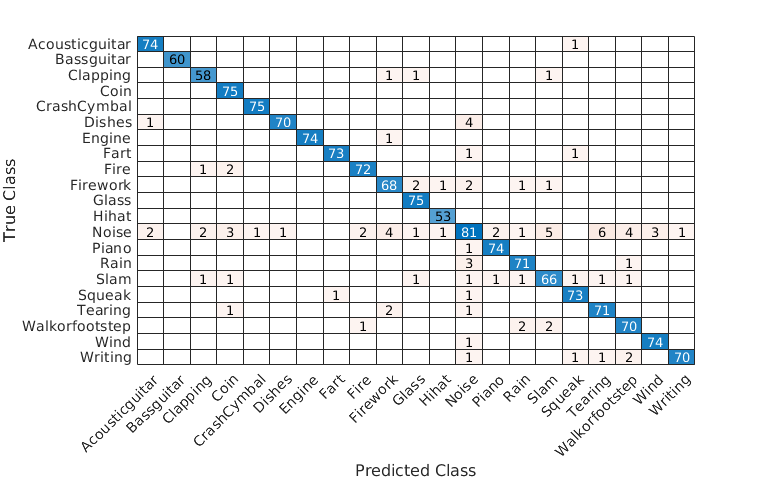

%cm.Title = 'Confusion matrix';

% Add column and row summaries.

%cm.RowSummary = 'row-normalized';
%cm.ColumnSummary = 'column-normalized';
%sortClasses(cm,'descending-diagonal')

%set(findobj(gca,'type','text'),'fontsize',100);
set(findall(gcf,'-property','FontSize'),'FontSize',14); % All font size

## Evalucation metrics for each class (precision, recall, sensitivity, ...)

cms = confusionmatStats(Y,YPred);


recall(isnan(recall))=[];

Recall=Recall*sum(recall)./size(confMat,1);
%%% precision
for i =1:size(confMat,1)
    precision(i)=confMat(i,i)./sum(confMat(:,i));
end
Precision=sum(precision)./size(confMat,1);
%%% F-score
F_score=2.*Recall.*Precision./(Precision+Recall); %%F_score=2*1/((1/Precision)+(1/Recall));

## Test network on the testing sound 

% %load('net.mat');

% 
% dataFolderTest = '/media/thanh/Samsung_T5/BackupData/3rdYear/1.EUSIPCO/24Jan2021/evaluation-20210128T080955Z-001/evaluation/1. Aucoustic guitar/252380/';
% imdsTestFullData = imageDatastore(dataFolderTest);
% 

## Resize testing image to the required input size

% 
% augimdsTestFullData = augmentedImageDatastore(inputSize(1:2), imdsTestFullData);
% 

## Test model on test dataset

% 
% [YPredTest,probs] = classify(net,augimdsTestFullData);


## Evalucation

function stats = confusionmatStats(group,grouphat)
% INPUT
% group = true class labels
% grouphat = predicted class labels
%
% OR INPUT
% stats = confusionmatStats(group);
% group = confusion matrix from matlab function (confusionmat)
%
% OUTPUT
% stats is a structure array
% stats.confusionMat
%               Predicted Classes
%                    p'    n'
%              ___|_____|_____| 
%       Actual  p |     |     |
%      Classes  n |     |     |
%
% stats.accuracy = (TP + TN)/(TP + FP + FN + TN) ; the average accuracy is returned
% stats.precision = TP / (TP + FP)                  % for each class label
% stats.sensitivity = TP / (TP + FN)                % for each class label
% stats.specificity = TN / (FP + TN)                % for each class label
% stats.recall = sensitivity                        % for each class label
% stats.Fscore = 2*TP /(2*TP + FP + FN)            % for each class label
%
% TP: true positive, TN: true negative, 
% FP: false positive, FN: false negative
% 

field1 = 'confusionMat';
if nargin < 2
    value1 = group;
else
    [value1,gorder] = confusionmat(group,grouphat);
end

numOfClasses = size(value1,1);
totalSamples = sum(sum(value1));

[TP,TN,FP,FN,accuracy,sensitivity,specificity,precision,f_score] = deal(zeros(numOfClasses,1));
for class = 1:numOfClasses
   TP(class) = value1(class,class);
   tempMat = value1;
   tempMat(:,class) = []; % remove column
   tempMat(class,:) = []; % remove row
   TN(class) = sum(sum(tempMat));
   FP(class) = sum(value1(:,class))-TP(class);
   FN(class) = sum(value1(class,:))-TP(class);
end

for class = 1:numOfClasses
    accuracy(class) = (TP(class) + TN(class)) / totalSamples;
    sensitivity(class) = TP(class) / (TP(class) + FN(class));
    specificity(class) = TN(class) / (FP(class) + TN(class));
    precision(class) = TP(class) / (TP(class) + FP(class));
    f_score(class) = 2*TP(class)/(2*TP(class) + FP(class) + FN(class));
end

field2 = 'accuracy';  value2 = accuracy;
field3 = 'sensitivity';  value3 = sensitivity;
field4 = 'specificity';  value4 = specificity;
field5 = 'precision';  value5 = precision;
field6 = 'recall';  value6 = sensitivity;
field7 = 'Fscore';  value7 = f_score;
stats = struct(field1,value1,field2,value2,field3,value3,field4,value4,field5,value5,field6,value6,field7,value7);
if exist('gorder','var')
    stats = struct(field1,value1,field2,value2,field3,value3,field4,value4,field5,value5,field6,value6,field7,value7,'groupOrder',gorder);
end
    
end